syms alpha beta gamma real
R_yxz = rpy_rotation("yxz", [alpha, beta, gamma])

$$R\_yxz = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & -\cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)+\cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right)\\ \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\beta \right)\,\cos\left(\gamma \right) & \sin\left(\alpha \right)\,\sin\left(\gamma \right)-\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ -\cos\left(\beta \right)\,\sin\left(\alpha \right) & \sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$


isRotationMatrix(R_yxz)

ans = logical
   1


P1 = [1.5 1]'

P1 =     1.5000
    1.0000


P2 = [0.5 1.5]'

P2 =     0.5000
    1.5000


T = 3.2

T = 3.2000

C = P1 + (P2-P1)/2

C =     1.0000
    1.2500


R = norm(P2-P1)/2

R = 0.5590


sin_phi = (P1(2)-C(2))/R;
cos_phi = (P1(1)-C(1))/R;
PHI = abs(atan2(sin_phi, cos_phi))

PHI = 0.4636

rad2deg(PHI)

ans = 26.5651

syms t positive real
tau = t/T

$$tau = \frac{5\,t}{16}$$

s = cubic_poly_double_norm(-2, 3, 0, 0, tau, 0, 1);
p = C + R*[cos(2*pi*s-PHI);
            -sin(2*pi*s-PHI)]

$$p = \left(\begin{array}{c} \frac{\sqrt{5}\,\cos\left(2\,\pi \,\left(\frac{75\,t^{2}}{256}-\frac{125\,t^{3}}{2048}\right)-\frac{8352332796509007}{18014398509481984}\right)}{4}+1\\ \frac{5}{4}-\frac{\sqrt{5}\,\sin\left(2\,\pi \,\left(\frac{75\,t^{2}}{256}-\frac{125\,t^{3}}{2048}\right)-\frac{8352332796509007}{18014398509481984}\right)}{4} \end{array}\right)$$

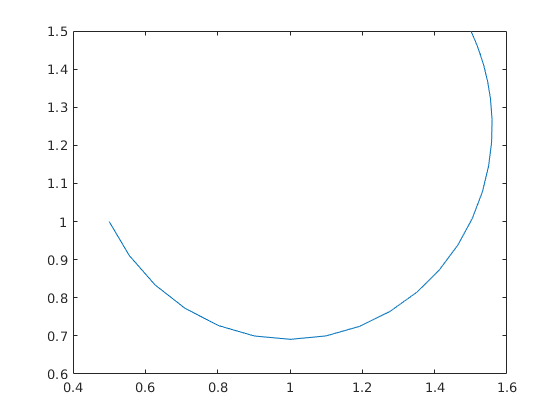

hold off

th = 0:T/50:T/2;
xunit = subs(p(1), {t}, {th});
yunit = subs(p(2), {t}, {th});
h = plot(xunit, yunit);
hold off

hold off

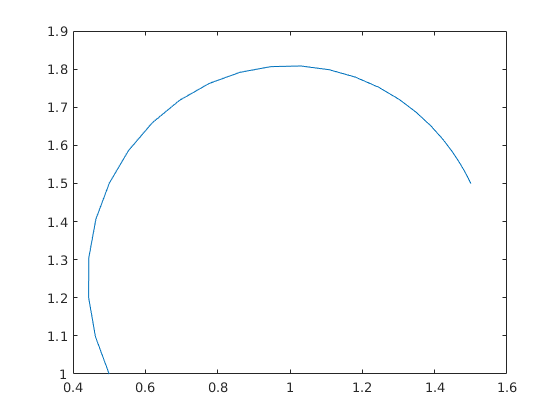

th = T/2:T/50:T;
xunit = subs(p(1), {t}, {th});
yunit = subs(p(2), {t}, {th});
h = plot(xunit, yunit);
hold off

p_dot = diff(p, t)

$$p\_dot = \begin{array}{l} \left(\begin{array}{c} -\frac{\pi \,\sqrt{5}\,\sin\left(\sigma_{1}\right)\,\left(\frac{75\,t}{128}-\frac{375\,t^{2}}{2048}\right)}{2}\\ -\frac{\pi \,\sqrt{5}\,\cos\left(\sigma_{1}\right)\,\left(\frac{75\,t}{128}-\frac{375\,t^{2}}{2048}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\pi \,\left(\frac{75\,t^{2}}{256}-\frac{125\,t^{3}}{2048}\right)-\frac{8352332796509007}{18014398509481984} \end{array}$$

p_dd = simplify(diff(p_dot, t))

$$p\_dd = \begin{array}{l} \left(\begin{array}{c} \frac{\pi \,\sqrt{5}\,\sin\left(\sigma_{1}\right)\,\left(\frac{375\,t}{1024}-\frac{75}{128}\right)}{2}-\sqrt{5}\,\pi^{2}\,\cos\left(\sigma_{1}\right)\,\sigma_{2}\\ \frac{\pi \,\sqrt{5}\,\cos\left(\sigma_{1}\right)\,\left(\frac{375\,t}{1024}-\frac{75}{128}\right)}{2}+\sqrt{5}\,\pi^{2}\,\sin\left(\sigma_{1}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\pi \,\left(\frac{75\,t^{2}}{256}-\frac{125\,t^{3}}{2048}\right)-\frac{8352332796509007}{18014398509481984}\\ \sigma_{2}={\left(\frac{75\,t}{128}-\frac{375\,t^{2}}{2048}\right)}^{2} \end{array}$$

rob = robot_planar_RP();
syms q1 q2 real 
p = eval(subs(rob.p, {q1, q2}, {-4, 5}))

p =    -3.2682
    3.7840
         0


[q1 q2] = rob.inverse(p, 'neg')

q1 = -0.8584

q2 = -5

q1 = eval(q1)

Error using eval
Must be a string scalar or character vector.

q2= eval(q2)

eval(rob.direct(q1, q2))

ans =    -3.2682
    3.7840
         0
